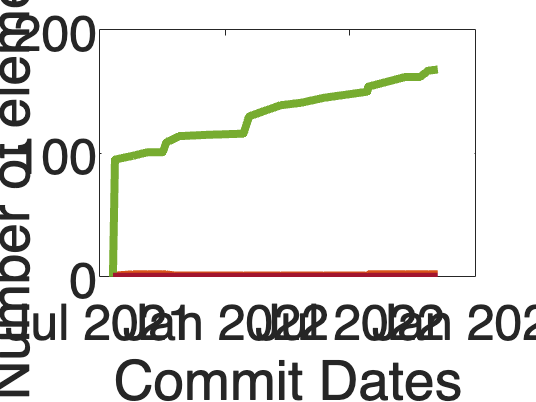

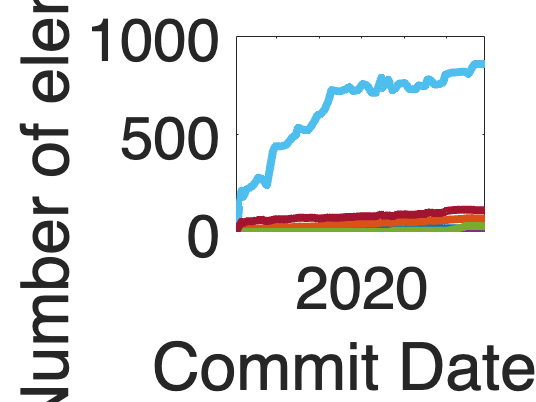

% Create a figure and invisible axes
fig = figure('visible', 'off');
ax = axes(fig, 'visible', 'off');

% Create a dummy bar chart for the legend
b = bar(nan(7, 7), 'stacked');
b(2).FaceColor = "#D95319";
b(1).FaceColor = "#0072BD";

% Create the legend with a larger font size
lgd = legend("Swift - UIViews", "Swift - UIViewControllers", "ObjC - UIViews", "ObjC - UIViewControllers", "SwiftUI Views", "Storyboard or XIB Views", "Storyboard or XIB View Controllers");
set(lgd, 'FontSize', 15, 'NumColumns', 7, 'Location', 'north', 'Orientation', 'horizontal', 'Units', 'pixels');
lgd.Position = [10, 10, lgd.Position(3:4)]; % Adjust position to reduce white space

% Adjust figure size based on legend
fig.Units = 'pixels';
fig.Position = [fig.Position(1:2), lgd.Position(3) + 20, lgd.Position(4) + 20];

% Remove the axes
axis off;

% Save the legend as a PDF, cropped to size
%exportgraphics(ax, './ui/uilegend.pdf', 'ContentType', 'vector');


appsWithSwiftUI = [];
appsStartingWithSwiftUI = [];
for i=1:length(data)
    if data{i, 10}(end).SwiftUIViews.count > 0
    appsWithSwiftUI(end+1) = i;
    end
    if data{i, 10}(1).SwiftUIViews.count > 0
    appsStartingWithSwiftUI(end+1) = i;
    end
end

sizes = zeros(length(appsWithSwiftUI), 1);
s = 1;
for i=[105 109 74 22]
    UIViewsSwift = [];
    UIViewControllersSwift = [];
    UIViewsObjC = [];
    UIViewControllersObjC = [];
    swiftUIViews = [];
    storyboardViews = [];
    storyboardViewControllers = [];
    xibViews = [];
    xibViewControllers = [];
    dates = datetime;
    
    for j=1:length(data{i, 10})
        UIViewsSwift(end + 1) = data{i, 10}(j).UIKitViewsSwift.count;
        UIViewControllersSwift(end + 1) = data{i, 10}(j).UIKitViewControllersSwift.count;
        UIViewsObjC(end + 1) = data{i, 10}(j).UIKitViewsObjC.count;
        UIViewControllersObjC(end + 1) = data{i, 10}(j).UIKitViewControllersObjC.count;
        swiftUIViews(end + 1) = data{i, 10}(j).SwiftUIViews.count;
        views = zeros(22, 1);
        viewControllers = zeros(11, 1);
        xibInViews = zeros(22, 1);
        xibInViewControllers = zeros(11, 1);
        for t=1:length(data{i, 10}(j).Storyboards)
            if isfield(data{i, 10}(j).Storyboards(t), "views")
                views = views + data{i, 10}(j).Storyboards(t).views;
            end
            if isfield(data{i, 10}(j).Storyboards(t), "viewControllers")
            viewControllers = viewControllers + data{i, 10}(j).Storyboards(t).viewControllers;
            end
        end
        for t=1:length(data{i, 10}(j).xibs)
            if isfield(data{i, 10}(j).xibs(t), "views")
                xibInViews = views + data{i, 10}(j).xibs(t).views;
            end
            if isfield(data{i, 10}(j).xibs(t), "viewControllers")
            xibInViewControllers = xibInViewControllers + data{i, 10}(j).xibs(t).viewControllers;
            end
        end
        storyboardViews(end + 1) = sum(views) + sum(xibInViews);
        storyboardViewControllers(end + 1) = sum(viewControllers) + sum(xibInViewControllers);
        dates(end + 1) = data{i, 10}(j).dateTime;
    end
    dates(1) = [];

    dim = UIViewsSwift(end) + UIViewControllersSwift(end) + UIViewsObjC(end)+ UIViewControllersObjC(end) + swiftUIViews(end) + storyboardViews(end) + storyboardViewControllers(end);
    sizes(s) = dim;
    s = s + 1;

    f = figure('Name',  i + " " + data{i, 8});
    f.Position = [100, 100, 1200, 900];

    Y = [UIViewsSwift', UIViewControllersSwift', UIViewsObjC', UIViewControllersObjC', swiftUIViews', storyboardViews', storyboardViewControllers'];
    plot(dates, Y, 'LineWidth', 4);
   

    xlabel("Commits", 'FontSize', 30);
    ylabel("Lines of Code", 'FontSize', 30);
    
    % Set font size for axes ticks
    set(gca, 'FontSize', 30);
    
    % Adjust PaperPosition and PaperSize to minimize white space
    set(f, 'PaperPositionMode', 'auto');
    set(f, 'PaperUnits', 'inches');
    set(f, 'PaperPosition', [0 0 12 9]);
    set(f, 'PaperSize', [12 9]);

    %legend("Swift - UIViews", "Swift - UIViewControllers", "ObjC - UIViews", "ObjC - UIViewControllers", "SwiftUI Views", "Storyboard or XIB Views", "Storyboard or XIB View Controllers")
    xlabel("Commit Dates")
    ylabel("Number of elements")
    print(f, ['./ui/app_' num2str(i)], '-dpdf', '-r0');

end

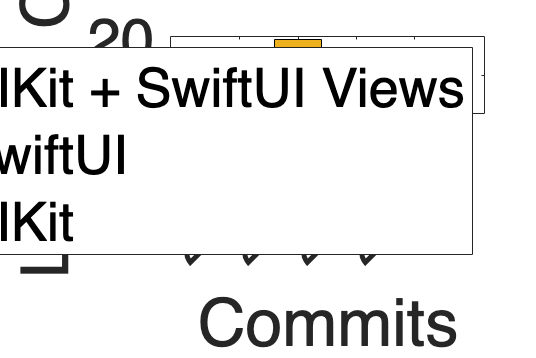



f = figure;

f.Position = [100, 100, 1200, 800]; % Width: 1200, Height: 600

bar([2019, 2020, 2021, 2022], [UIKitCounts; swiftUICounts; bothCounts], 'stacked');

legend("UIKit", "SwiftUI", "UIKit + SwiftUI Views")
xlabel('Year of the first commit') 
ylabel('Number of apps') 

xlabel("Commits", 'FontSize', 30);
ylabel("Lines of Code", 'FontSize', 30);

% Set font size for axes ticks
set(gca, 'FontSize', 30);


% Adjust figure's paper size and position to match its content
set(f, 'PaperPositionMode', 'auto');
set(f, 'PaperUnits', 'points');
set(f, 'PaperSize', [1200 800]);
set(f, 'PaperPosition', [0 0 1200 800]);

print(f, ['./ui/recap'], '-dpdf', '-r0');